addpath('./functions');
addpath('./data');

load('bignet.mat')
load('ood_detection.mat')
[XTrain, YTrain, XTest, YTest] = load_data('data');

analyzeNetwork(bignet)

layer = "relu_10"

layer = "relu_10"

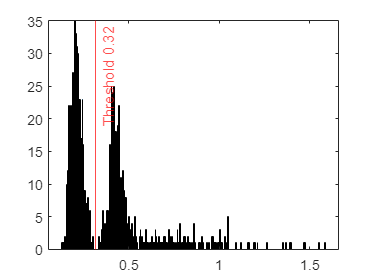

features = activations(bignet, ood_detection.data, layer, OutputAs="rows");
histogram(mean(features,2), NumBins=300)
threshold = 0.32;
xline(threshold,"r-",join(["Threshold" threshold]))

pred = mean(featuresTest,2)<threshold;
y_test = ood_detection.labels== 'ood';
tp = nnz(pred == y_test);
accuracy = tp / length(y_test);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 100%


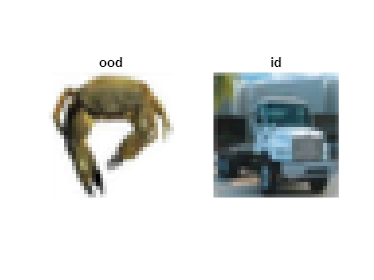

ood = find(ood_detection.labels=='ood');
id = find(ood_detection.labels=='id');
subplot(1,2,1);
imshow(ood_detection.data(:,:,:,datasample(ood,1)));
title("ood")
subplot(1,2,2);
imshow(ood_detection.data(:,:,:,datasample(id,1)));
title("id")